Création d'un PhasorArray aleatoire, grace à l'argument "time_structure" qui specifie hurwitz

h=15;
nx=6;
T=1 %period

T = 1

A=(PhasorArray(rand_phasor(nx,nx,5,"time_structure","hurwitz","hurwitzeig",[(-1:-1:-nx)/10-2]))); %Creation d'un objet de classe PhasorArray
A=mreal(A); %to extract only real part of A, rand_phasor often produce complexe valued periodic matrices


N=NTB(nx,h,T);

figure(10)
clf
stem(A)
sgtitle('Stem of A')

HmqNeig vient calculer les eigein value de (A-N), à condition que A represente une matrice carrée périodique

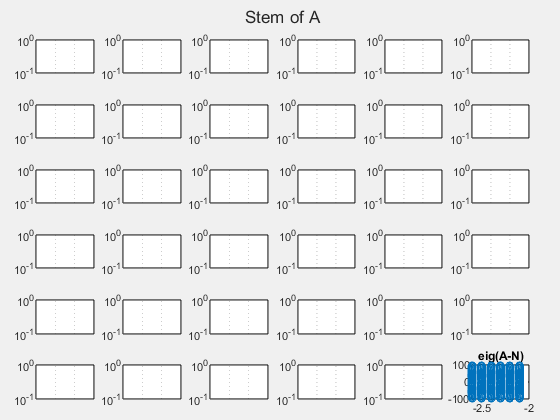

figure(11)
plot(A.HmqNEig(h,T),'o')
title('eig(A-N)')


figure(12)
hmq_sim(A.Value,10,rand(nx,1),1,"plot",true);

2566 successful steps
0 failed attempts
2607 function evaluations
1 partial derivatives
39 LU decompositions
2605 solutions of linear systems


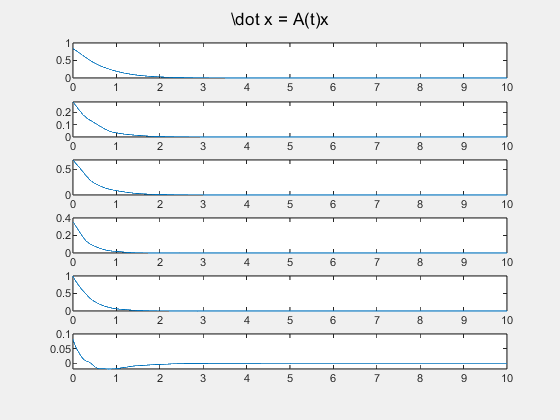

sgtitle("\dot x = A(t)x",'Interpreter','tex')

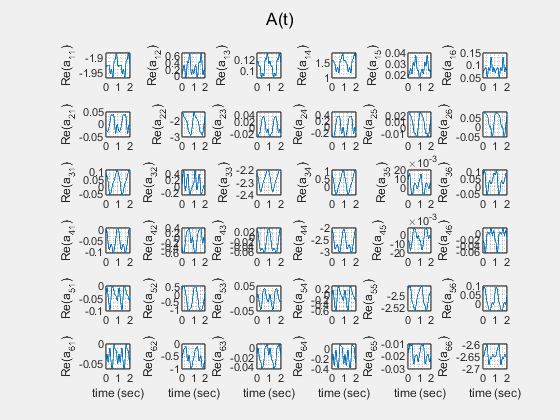


figure(13)
plot(A,T,0:0.01:2,title='A(t)')

## stabilité

### En realisant le produit avant entre phasor, puis en construitant le probleme TB LMI

h=10

h = 10


P2=sdpvar(size(A,1),size(A,2),h,'symmetric','complex');
P1=ndsdpvar(size(A,1),size(A,2),1,'symmetric','real');
P = PosPart2PhasorArray(P1,P2);

PT=P.TB(h);
t1=tic();

%produits entre les objets phaseur
ATP=(A.')*P;
PA=P*A;
ATPpPA=(ATP+PA)

ATPpPA = 6x6x31 PhasorArray of ndsdpvar representing a 6x6 real-valued periodic matrix with 15 harmonics


%Construction de la Toeplitz Blocks Matrix (matrice à blocs toeplitz)
ATPpPA.TB(h);

F=[PT>=0,ATPpPA.TB(h) + NTB(nx,h,1)*PT-PT*NTB(nx,h,1)<=-(eye(size(A.TB(h),1))*10)]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                            Constraint|       Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (complex) 126x126|                  1 to 1|
|   #2|   Matrix inequality (complex) 126x126|   7.6973e-06 to 62.8319|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++


toc(t1)

Elapsed time is 1.723218 seconds.


optimize(F)


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 441             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.02            
Lin. dep.  - number

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2923080 (R2024b) Update 6'
       yalmiptime: 1.8761
       solvertime: 2.7759
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


toc(t1)

Elapsed time is 6.396039 seconds.


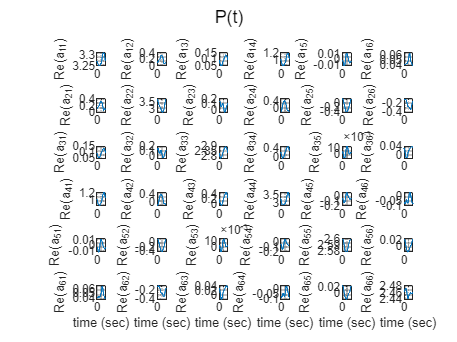

%
Pf=sdpval(P);

figure(20)
Pf.plot
sgtitle("P(t)")

### Stabilité, mais avec les matrices de Hankel

h=10

h = 10


t1=tic();
P2=sdpvar(size(A,1),size(A,2),h,'symmetric','complex');
P1=ndsdpvar(size(A,1),size(A,2),1,'symmetric','real');
P = PosPart2PhasorArray(P1,P2);

PT=P.TB(h);
ATB=A.TB(h);

[AHpJ,AJHm,AHp,AHm]=A.TBHankel(h);
[AtHpJ,AtJHm,AtHp,AtHm]=TBHankel(A.',h);
[PHpJ,PJHm,PHp,PHm]=P.TBHankel(h);
F=[PT>=0;
(ATB'+NTB(A,h))*PT+PT*(ATB-NTB(A,h))+...
AtHp*PHm+PHp*AHm+...
AtJHm*PHpJ+PJHm*AHpJ<=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                            Constraint|       Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (complex) 126x126|                  1 to 1|
|   #2|   Matrix inequality (complex) 126x126|   1.3553e-20 to 62.8319|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



toc(t1)

Elapsed time is 0.557653 seconds.


optimize(F)


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 441             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2923080 (R2024b) Update 6'
       yalmiptime: 3.4164
       solvertime: 5.6686
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0


toc(t1)

Elapsed time is 9.658274 seconds.


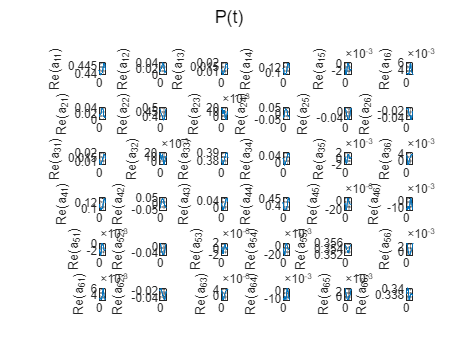

%
Pf=sdpval(P);

figure(21)
clf
Pf.plot
sgtitle("P(t)")

## quadratic stability

hP=10;
h=10;
hb=3

hb = 3


nx=2

nx = 2

nu=2

nu = 2


T=5;

A=mreal(rand_phasor(nx,nx,hb,output="PhasorArray"))

A = 2x2x7 PhasorArray of double representing a 2x2 real-valued periodic matrix with 3 harmonics


Q=PhasorArray.ndsdpvar(nx,nx,hP,PhasorType='symmetric')

Q = 2x2x21 PhasorArray of ndsdpvar representing a 2x2 real-valued periodic matrix with 10 harmonics

QT=Q.TB(h);

%produits entre les objets phaseur
QAT=Q*(A.')

QAT = 2x2x27 PhasorArray of ndsdpvar representing a 2x2 real-valued periodic matrix with 13 harmonics

AQ=A*Q

AQ = 2x2x27 PhasorArray of ndsdpvar representing a 2x2 real-valued periodic matrix with 13 harmonics

QATpAQ=(QAT+AQ)

QATpAQ = 2x2x27 PhasorArray of ndsdpvar representing a 2x2 real-valued periodic matrix with 13 harmonics

% LMI=QATpAQ+Y+(Y.')

%Construction de la Toeplitz Blocks Matrix (matrice à blocs toeplitz)
QATpAQ.TB(2*h);


B=rand_phasor(nx,nu,hb);
Y=PhasorArray.ndsdpvar(nx,nx,hP,PhasorType='full')

Y = 2x2x21 PhasorArray of ndsdpvar representing a 2x2 real-valued periodic matrix with 10 harmonics


F=[QT>=eye(size(QT))];
N=NTB(A,h,T);
F=[F,[QATpAQ.TB(h)-N*QT+QT*N+Y.TB(h)+Y.TB(h)'] <=-8*QT]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                          Constraint|       Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (complex) 42x42|                  1 to 1|
|   #2|   Matrix inequality (complex) 42x42|   0.00029714 to 15.6314|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



optimize(F,-trace(Y.phas(0)))


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 147             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2923080 (R2024b) Update 6'
       yalmiptime: 0.1509
       solvertime: 0.1861
             info: 'Unbounded objective function (<a href="yalmip.github.io/debuggingunbounded">learn to debug</a>) (MOSEK-SDP)'
          problem: 2


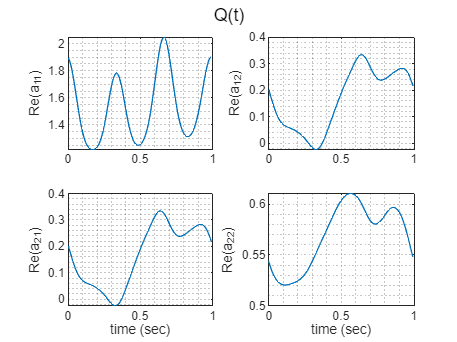



%
Pf=sdpval(P);

figure(22)
Q.plot(explosed=true);
sgtitle("Q(t)")

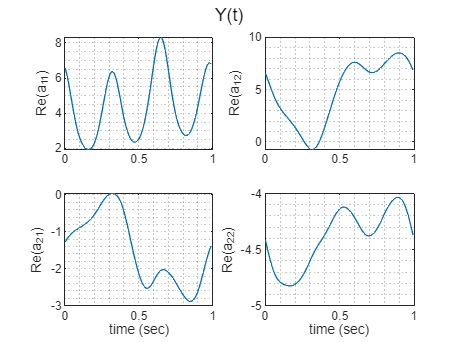



figure(23)
Y.plot(explosed=true);
sgtitle("Y(t)")



K=Y/Q;
K=PhasorArray(value(value(K)))

K = 2x2x275 PhasorArray of double representing a 2x2 real-valued periodic matrix with 137 harmonics

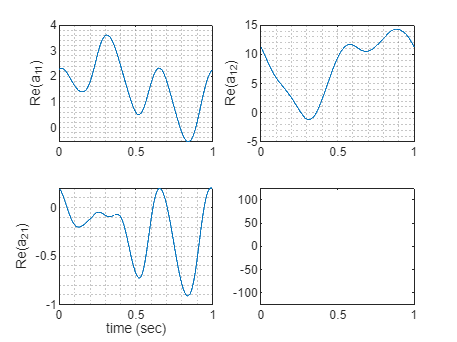

figure(24)
plot(K)

figure(25)
plot(A.HmqNEig,'*')
hold on
plot(HmqNEig(A+K),'o')

826 successful steps
0 failed attempts
835 function evaluations
1 partial derivatives
7 LU decompositions
833 solutions of linear systems


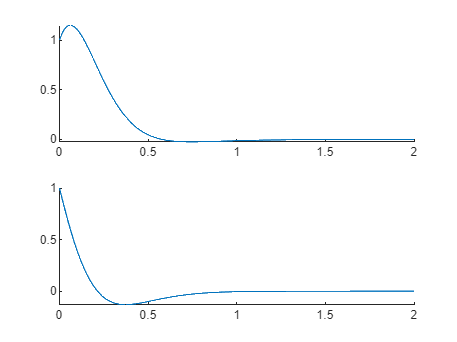


figure(26)
lsim(A+K,2,[],T);

## LQ reg H2

nx=3;
nu=3;
nha=3;
hP=10;
h=10;

T=1/2/pi

T = 0.1592

x0=[1 0 0]

x0 =      1     0     0



Q=eye(nx)

Q =      1     0     0
     0     1     0
     0     0     1


R=eye(nu)

R =      1     0     0
     0     1     0
     0     0     1



A=mreal(rand_phasor(nx,nx,nha,'output','PhasorArray'));
B=mreal(rand_phasor(nx,nu,nha,'output','PhasorArray'));

X=PhasorArray.ndsdpvar(nx,nx,hP);
W=PhasorArray.ndsdpvar(nu,nx,hP,'PhasorType','full','real',1);
Y=PhasorArray.ndsdpvar(nu,nu,hP)

Y = 3x3x21 PhasorArray of ndsdpvar representing a 3x3 real-valued periodic matrix with 10 harmonics

Gam=sdpvar(1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1



M1=(A*X+B*W)+(A*X+B*W).'+x0*x0';
M2=phas(trace((Q^0.5)*X*(Q^0.5).')+trace(Y),0);
M3=[-Y (R^0.5)*W;((R^0.5)*W).' -X];


N=NTB(A,h,T);
F=[[M1.TB(h)-N'*X.TB(h)-X.TB(h)*N<=0];...
    M2<=Gam;...
    M3.TB(h)<=0]

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                            Constraint|        Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|     Matrix inequality (complex) 63x63|   5.6154e-05 to 394.7842|
|   #2|           Element-wise inequality 1x1|                   1 to 1|
|   #3|   Matrix inequality (complex) 126x126|                   1 to 1|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



obj=Gam

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1



optimize(F,obj)


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 442             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 1               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2923080 (R2024b) Update 6'
       yalmiptime: 0.3874
       solvertime: 1.6446
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0



K=(W/X)%display controller matrix

K = 3x3x275 PhasorArray of ndsdpvar representing a 3x3 real-valued periodic matrix with 137 harmonics

K=PhasorArray(value(value(K)))

K = 3x3x275 PhasorArray of double representing a 3x3 real-valued periodic matrix with 137 harmonics

figure(27)
plot(K)


figure(28)
plot(A.HmqNEig(h,T),'*')
hold on
plot((HmqNEig(A+B*K,h,T)),'o')

figure(29)
lsim(A+B*K,2,[],T);

25737 successful steps
0 failed attempts
50010 function evaluations
1 partial derivatives
6 LU decompositions
50008 solutions of linear systems



value(value(Gam))

ans = 1.6688

## Another H_2 

nx=3;
nu=3;
ny=2

ny = 2

nha=3;
hP=10;
h=10;


A=mreal(rand_phasor(nx,nx,nha,'output','PhasorArray'));
B=mreal(rand_phasor(nx,nu,nha,'output','PhasorArray'));
B=mreal(rand_phasor(ny,nx,nha,'output','PhasorArray'));

X=PhasorArray.ndsdpvar(nx,nx,hP);
W=PhasorArray.ndsdpvar(nu,nx,hP,'PhasorType','full','real',1);
Y=PhasorArray.ndsdpvar(nu,nu,hP)

Y = 3x3x21 PhasorArray of ndsdpvar representing a 3x3 real-valued periodic matrix with 10 harmonics

Gam=sdpvar(1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1


## LQR

nx=3;
nu=3;
ny=2

ny = 2

nha=3;
hP=10;
h=10;

T=1/10

T = 0.1000



A=mreal(rand_phasor(nx,nx,nha,'output','PhasorArray'));
B=mreal(rand_phasor(nx,nu,nha,'output','PhasorArray'));
C=mreal(rand_phasor(ny,nx,nha,'output','PhasorArray'));


Y=PhasorArray.ndsdpvar(nx,nx,hP);
L=PhasorArray.ndsdpvar(nu,nu,hP)

L = 3x3x21 PhasorArray of ndsdpvar representing a 3x3 real-valued periodic matrix with 10 harmonics

Gam=sdpvar(1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1



%Forme Toeplitz Block de Q 
YT=Y.TB(h);

B=PhasorArray(eye(nx));
LMI=(A*Y + B*L)+(A*Y+B*L).';

Ql= PhasorArray(diag(10*ones(nx,1)));
Rl= PhasorArray(diag(1*ones(nx,1)));

F=[YT>=0];
N=NTB(A,h,T);

F=[F,[-(LMI.TB(h)-N*YT-YT*N'), Y.TB(h) , L.TB(h)';
Y.TB(h) , TB(Ql^-1,h),  -zeros((2*h+1)*nx);
L.TB(h), -zeros((2*h+1)*nx), TB(Rl^-1,h)] >=0];

obj=-trace(Y).phas(0);
u=optimize(F,obj);


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 252             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number



figure(30)
Y.plot(plot=true,explosed=true);
sgtitle("Y(t)")


figure(31)
L.plot(plot=true,explosed=true);
sgtitle("L(t)")

if ~u.problem %si le solver a trouvé une solution
    K=L/Y;
end

K=K.sdpval

K = 3x3x275 PhasorArray of double representing a 3x3 real-valued periodic matrix with 137 harmonics

K=K.reduce("reduceMethod","relative","reduceThreshold",1e-4)

K = 3x3x21 PhasorArray of double representing a 3x3 real-valued periodic matrix with 10 harmonics

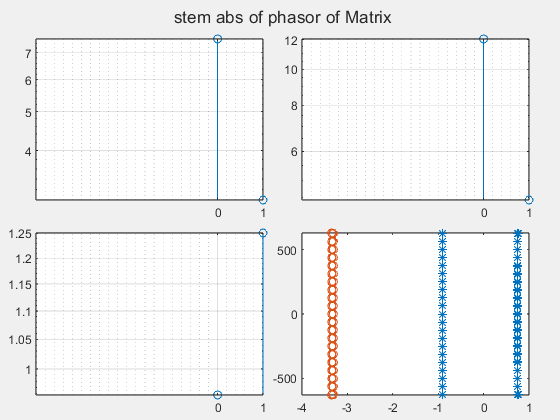


figure(34)
K.plot(plot=true,explosed=true);
sgtitle("K(t)")

figure(35)
K.stem
sgtitle("K")

figure(36)
plot(A.HmqNEig(h,T),'*')
hold on
plot(value(HmqNEig(A+B*K,h,T)),'o')

5124 successful steps
0 failed attempts
5320 function evaluations
1 partial derivatives
189 LU decompositions
5318 solutions of linear systems


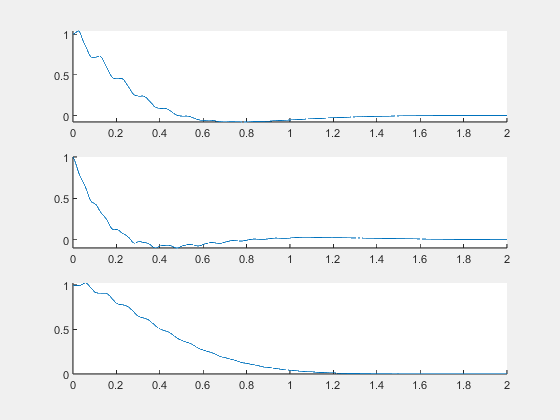


figure(37)
lsim(A+B*K,2,[],T);

## LQR

%liste de sdp var servant aux phaseur 
Q2=(sdpvar(size(A,1),size(A,2),h,'symmetric','complex'));
%sdpvar phaseur 0 (réel)
Q1=(ndsdpvar(size(A,1),size(A,2),1,'symmetric','real'));
%sdpvar phaseur array
Q = PosPart2PhasorArray(Q1,Q2);

%idem pour Y
Y=PhasorArray(PosPart2PhasorArray(sdpvar(size(A,1),size(A,2),1,'full','real'),sdpvar(size(A,1),size(A,2),h,'full','complex')))

Y = 3x3x21 PhasorArray of ndsdpvar representing a 3x3 real-valued periodic matrix with 10 harmonics


%Forme Toeplitz Block de Q 
QT=Q.TB(h);

B=PhasorArray(eye(nx));
LMI=(A*Q + B*Y)+(A*Q+B*Y).';

Ql= PhasorArray(diag(10*ones(nx,1)));
Rl= PhasorArray(diag(1*ones(nx,1)));


F=[QT>=0];
N=NTB(A,h,1);

F=[F,[LMI.TB(h)-N*QT-QT*N', -Q.TB(h) , -Y.TB(h)';
-Q.TB(h) , -TB(Ql^-1,h),  -zeros((2*h+1)*nx);
-Y.TB(h), -zeros((2*h+1)*nx), -TB(Rl^-1,h)] <=0];

obj=trace(Y);
u=optimize(F,obj.phas(0));


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 315             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number

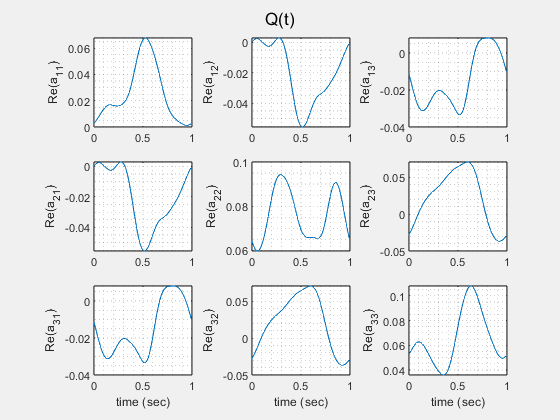



figure(40)
Q.plot(plot=true,explosed=true);
sgtitle("Q(t)")

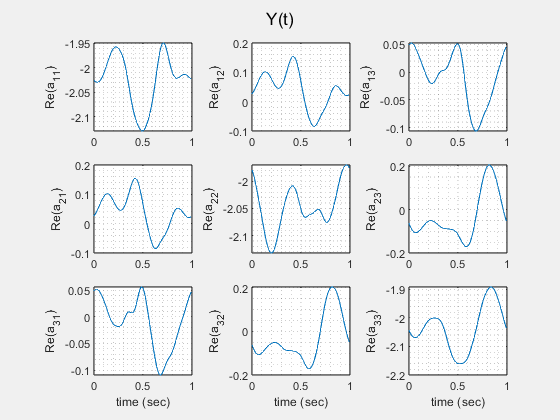



figure(41)
Y.plot(plot=true,explosed=true);
sgtitle("Y(t)")

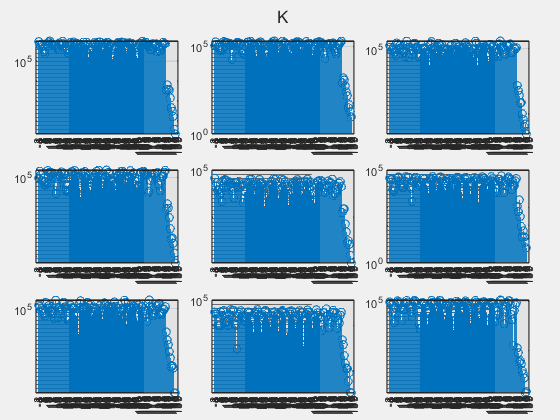


if ~u.problem %si le solver a trouvé une solution
    K=sdpval(Y)/sdpval(Q);
end

figure(42)
K.plot(plot=true,explosed=true);
sgtitle("K(t)")

figure(43)
K.stem
sgtitle("K")

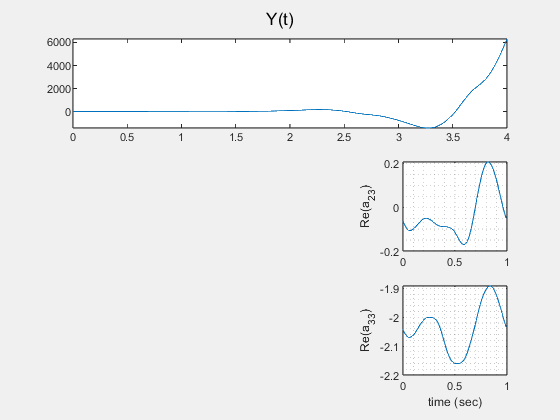

1033 successful steps
0 failed attempts
1094 function evaluations
1 partial derivatives
59 LU decompositions
1092 solutions of linear systems


x0=rand(nx,1);
figure(44)
subplot(121)
hmq_sim(A,4,x0,1,"plot",true);

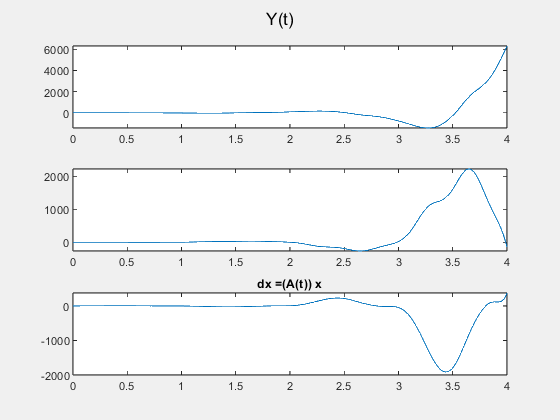

title("dx =(A(t)) x")


subplot(122)
hmq_sim(A+B*K,4,x0,1,"plot",true);

5301 successful steps
42 failed attempts
7954 function evaluations
18 partial derivatives
50 LU decompositions
7952 solutions of linear systems


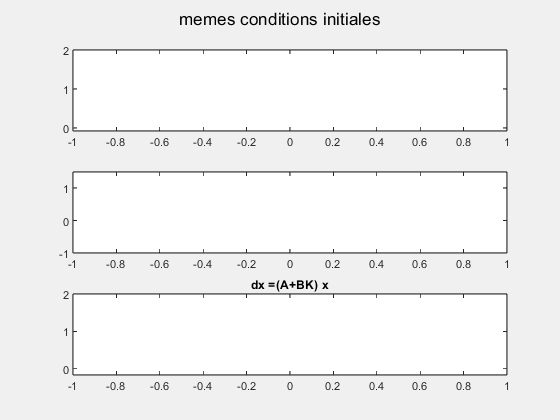

title("dx =(A+BK) x")
sgtitle('memes conditions initiales')

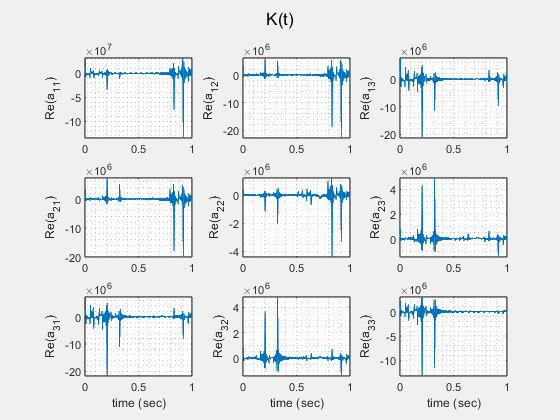


figure(45)
K.plot(plot=true,explosed=true);
sgtitle("K(t)")

## Riccati LMI


$$A^T P +PA -(PB +N^T)R^{-1}(B^T P +N) + Q \geq 0$$



$$\left[\matrix{A^TP +PA  +Q & PB +N^T \cr (PB +N^T)^T & R} \right] >0$$


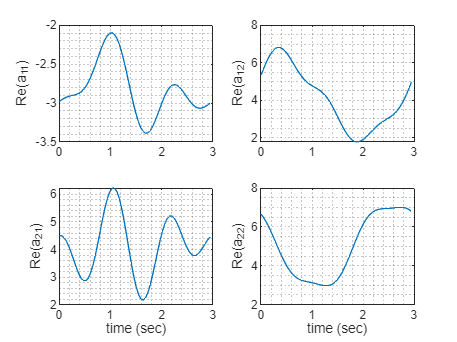

nx=2;
nu=2;

ha=3; %nombre de phasor dans A
hP=10; %nombre de phasor dans P, var de decision
h=10; %truncature order

T=3; %period

A=PhasorArray.random(nx,nx,ha,"time_structure","real");
figure(500)
clf
A.plot(T)

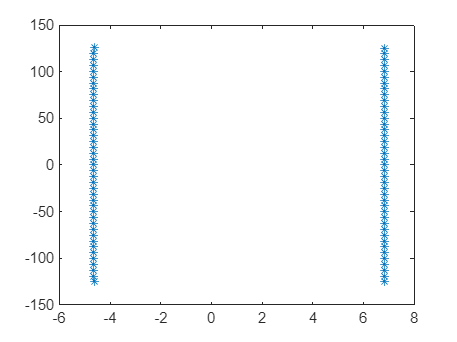

figure(501)
clf
plot(A.HmqNEig,'*')

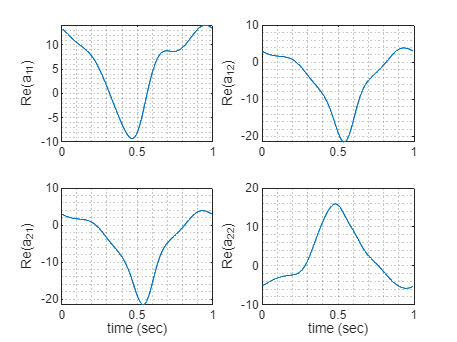



B=rand_phasor(nx,nu,ha,"output","PhasorArray");

%%%%% controllability criteria
%%% (A-N)W + W(A-N) + BB' iff Re(eig(A-N))<0

Pc=mreal(PhasorArray(Sylv_harmonique(A,A',B*B.',2*hP,1)));
figure(502)
plot(Pc)

trace(Pc).phas(0)

ans = 7.6603

 

%liste de sdp var servant aux phaseur 
P=PhasorArray.ndsdpvar(nx,nx,hP,"PhasorType",'symmetric',"real",true)

P = 2x2x21 PhasorArray of ndsdpvar representing a 2x2 real-valued periodic matrix with 10 harmonics

PT=P.TB(h);

Q=PhasorArray(eye(nx));
QT=Q.TB(h);

R=PhasorArray(eye(nu));
RT=Q.TB(h);

N=PhasorArray(zeros(nu,nx));


[AHpJ,AJHm,AHp,AHm]=A.TBHankel(h);
[AtHpJ,AtJHm,AtHp,AtHm]=TBHankel(A.',h);

[PHpJ,PJHm,PHp,PHm]=P.TBHankel(h);
[BHpJ,BJHm,BHp,BHm]=B.TBHankel(h);

ATB=A.TB(h);
BTB=B.TB(h);

NT=N.TB(h);

F0=[PT>=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                          Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (complex) 42x42|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



F11=[ATB'*PT+PT*ATB+...
AtHp*PHm+PHp*AHm+...
AtJHm*PHpJ+PJHm*AHpJ+...
NTB(A,h,T)*PT-PT*NTB(A,h,T)+QT];

F12=[PT*BTB+PHp*BHm+PJHm*BHpJ+NT'];

F21=F12';

F22=R.TB(h);

F1=[F11,F12;F21,F22];


F=[F0,F1>=0]

++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                          Constraint|      Coefficient range|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (complex) 42x42|                 1 to 1|
|   #2|   Matrix inequality (complex) 84x84|   3.4694e-18 to 20.944|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



obj=-trace(PT)

Linear scalar (real, 2 variables)
Coefficients range: 21 to 21


optimize(F,obj)


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 63              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2923080 (R2024b) Update 6'
       yalmiptime: 0.4723
       solvertime: 0.9597
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0




PP=PhasorArray(value(P.value))

PP = 2x2x21 PhasorArray of double representing a 2x2 real-valued periodic matrix with 10 harmonics

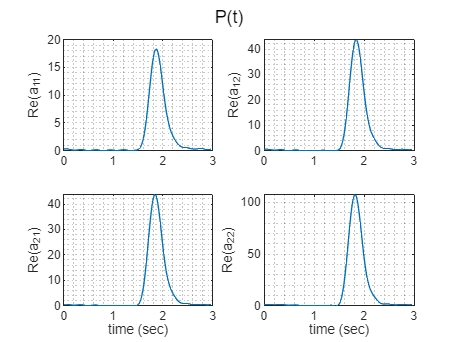

figure(503)
plot(PP,T,'title','P(t)')


K=R\(B.'*PP+N)

K = 2x2x27 PhasorArray of double representing a 2x2 real-valued periodic matrix with 13 harmonics

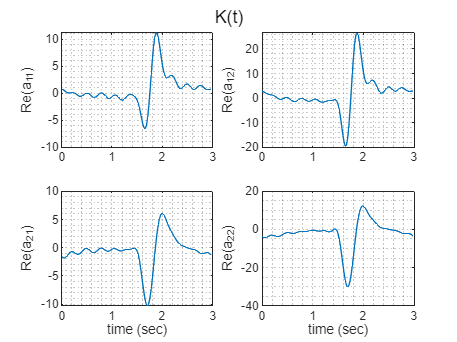


figure(504)
plot(K,T,'title','K(t)')

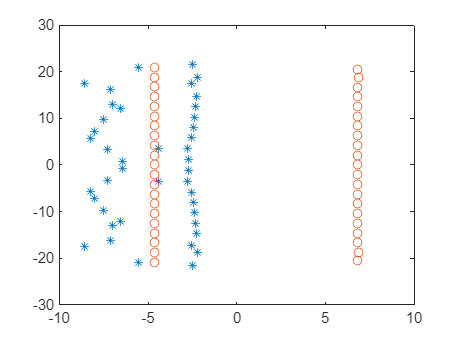


figure(505)
plot((HmqNEig(A-B*K,10,T)),'*')
hold on
plot((HmqNEig(A,10,T)),'o')


figure(506)
yyaxis left
lsim(A-B*K,10,[],T);

990 successful steps
19 failed attempts
1361 function evaluations
3 partial derivatives
109 LU decompositions
1359 solutions of linear systems


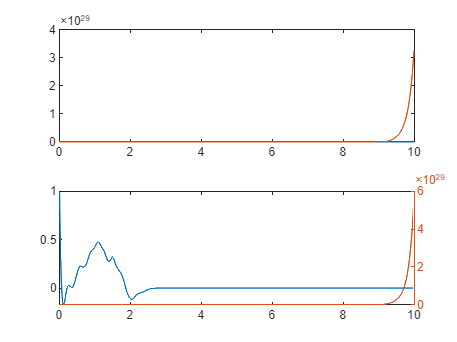

867 successful steps
0 failed attempts
890 function evaluations
1 partial derivatives
21 LU decompositions
888 solutions of linear systems



hold on
yyaxis right
lsim(A,10,[],T);

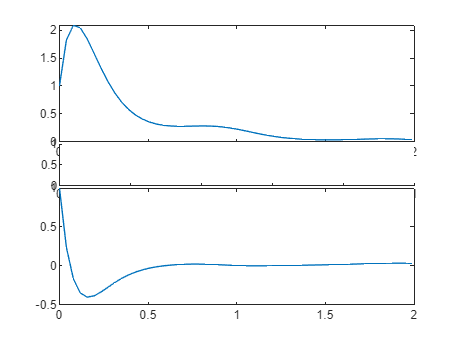

5209 successful steps
43 failed attempts
5939 function evaluations
1 partial derivatives
614 LU decompositions
5937 solutions of linear systems


ii = 2

1734 successful steps
31 failed attempts
2180 function evaluations
1 partial derivatives
200 LU decompositions
2178 solutions of linear systems


ii = 3

625 successful steps
16 failed attempts
915 function evaluations
1 partial derivatives
85 LU decompositions
913 solutions of linear systems


ii = 4

292 successful steps
18 failed attempts
553 function evaluations
2 partial derivatives
57 LU decompositions
551 solutions of linear systems


ii = 5

140 successful steps
5 failed attempts
232 function evaluations
1 partial derivatives
27 LU decompositions
230 solutions of linear systems


ii = 6



figure(507)
ii=1;
for T=logspace(-1,1,5)
subplot(5,1,ii)
lsim(A-B*K,2,[],T);
ii=ii+1
end

## H2 LMI


$$A^T P +PA +\gamma^{-1}PBB^T P + C^TC  \leq 0$$



$$\left[\matrix{A^TP +PA  +C^TC & PB  \cr (PB)^T & -\gamma I} \right] <0$$


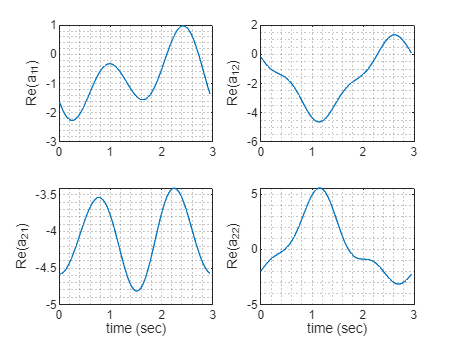

nx=2;
nu=2;
ny=2;

ha=3; %nombre de phasor dans A
hP=10 ;%nombre de phasor dans P, var de decision
h=10; %truncature order

T=3; %period

A=PhasorArray.random(nx,nx,ha);
figure(500)
clf
A.plot(T)

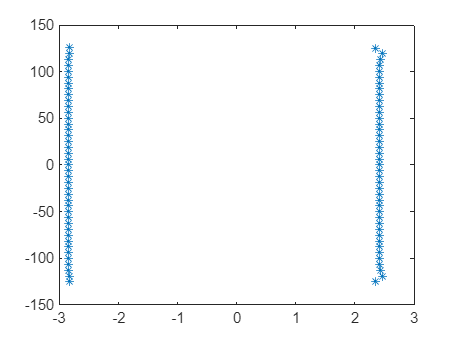

figure(501)
clf
plot(A.HmqNEig,'*')



B=PhasorArray.random(nx,nu,ha);
C=PhasorArray.random(ny,nx,ha);

gam=PhasorArray.ndsdpvar(1,1,0)*eye(nu)

gam = 2x2x1 PhasorArray of sdpvar representing a 2x2 real-valued periodic matrix with 0 harmonics


%sdpvar phaseur array
P = PhasorArray.ndsdpvar(nx,nx,hP);
PT=P.TB(h);

Q=C.'*C;
QT=Q.TB(h);

[AHpJ,AJHm,AHp,AHm]=A.TBHankel(h);
[AtHpJ,AtJHm,AtHp,AtHm]=TBHankel(A.',h);

[PHpJ,PJHm,PHp,PHm]=P.TBHankel(h);
[BHpJ,BJHm,BHp,BHm]=B.TBHankel(h);

ATB=A.TB(h);
BTB=B.TB(h);


F0=[PT>=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                          Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (complex) 42x42|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



F11=-[ATB'*PT+PT*ATB+...
AtHp*PHm+PHp*AHm+...
AtJHm*PHpJ+PJHm*AHpJ+...
NTB(A,h,T)*PT-PT*NTB(A,h,T)+QT];

F12=[PT*BTB+PHp*BHm+PJHm*BHpJ];

F21=F12';

F22=-gam.TB(h);

F1=[F11,F12;F21,F22];


F=[F0,F1<=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|                          Constraint|       Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality (complex) 42x42|                  1 to 1|
|   #2|   Matrix inequality (complex) 84x84|   5.2042e-18 to 27.0942|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++



obj=trace(gam{:,:,0})

Linear scalar (real, 1 variable)
Coefficients range: 2 to 2


optimize(F,obj)


MOSEK Version 10.0.38 (Build date: 2023-3-3 16:18:48)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 64              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 2               
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - number

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2923080 (R2024b) Update 6'
       yalmiptime: 0.8436
       solvertime: 2.3604
             info: 'Successfully solved (MOSEK-SDP)'
          problem: 0




PP=PhasorArray(value(P.value))

PP = 2x2x21 PhasorArray of double representing a 2x2 real-valued periodic matrix with 10 harmonics

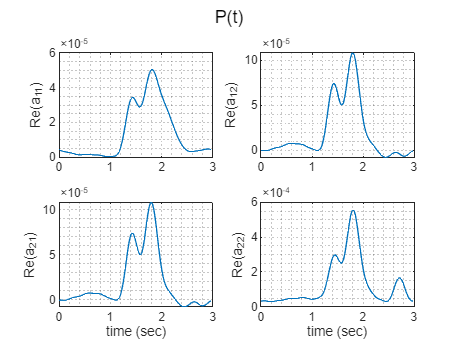

figure(601)
plot(PP,T,'title','P(t)')


K=value(value(gam))\(B.'*PP)

K = 2x2x27 PhasorArray of double representing a 2x2 real-valued periodic matrix with 13 harmonics

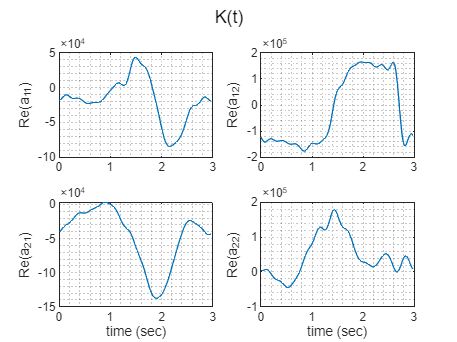


figure(602)
plot(K,T,'title','K(t)')

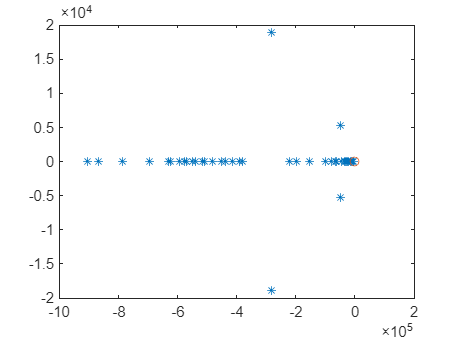


figure(603)
plot((HmqNEig(A-B*K,10,T)),'*')
hold on
plot((HmqNEig(A,10,T)),'o')

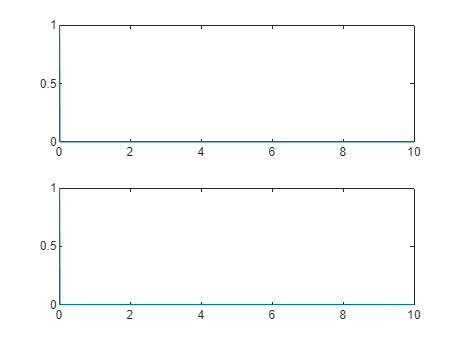

991 successful steps
40 failed attempts
1166 function evaluations
36 partial derivatives
70 LU decompositions
1164 solutions of linear systems



figure(604)
lsim(A-B*K,10,[],T);

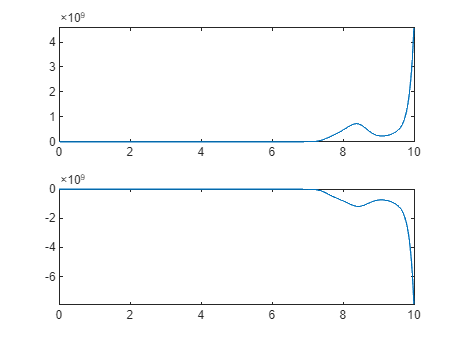

865 successful steps
0 failed attempts
910 function evaluations
1 partial derivatives
43 LU decompositions
908 solutions of linear systems



figure(605)
lsim(A,10,[],T);

figure(607)
ii=1

ii = 1

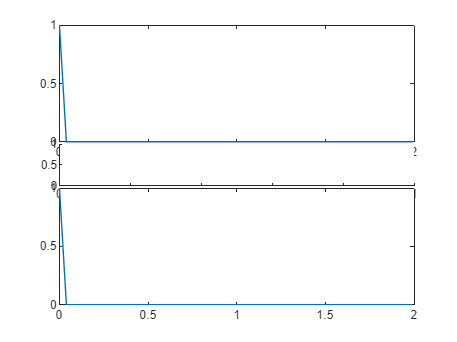

5340 successful steps
314 failed attempts
6438 function evaluations
264 partial derivatives
396 LU decompositions
6436 solutions of linear systems


ii = 2

1780 successful steps
117 failed attempts
2217 function evaluations
99 partial derivatives
163 LU decompositions
2215 solutions of linear systems


ii = 3

650 successful steps
31 failed attempts
786 function evaluations
26 partial derivatives
61 LU decompositions
784 solutions of linear systems


ii = 4

293 successful steps
9 failed attempts
359 function evaluations
8 partial derivatives
35 LU decompositions
357 solutions of linear systems


ii = 5

183 successful steps
2 failed attempts
234 function evaluations
2 partial derivatives
28 LU decompositions
232 solutions of linear systems


ii = 6

for T=logspace(-1,1,5)
subplot(5,1,ii)
lsim(A-B*K,2,[],T);
ii=ii+1
end